# calculate optimal Fisher Information for a certain tumour position

clc
clear

addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\NIRFAST-9.1'));
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\nirfast_fisher_numerical_311224'))
% addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\NIRFAST-9.1'));
% addpath(genpath('F:\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\nirfast_fisher_numerical_311224'))
mua_value = 0.033; % 0.01
mus_value = 1;

tumour_pos = [20,0];
tumour_radius = 15;

base_radius = 70;

dense_dist = 0.5;
base_dist = 0.5;

circle_mesh = gen_nonuni_circle_mesh(tumour_pos,max(tumour_radius)+2*dense_dist,dense_dist,base_radius,base_dist,mua_value,mus_value,1.33);

d_mua = 0.02;

## plot figure for the paper CSF

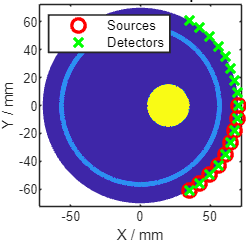

% -----------Desired sizes (cm)
figW = 17.2-12;   % figure width
figH = 17.2-12;    % figure height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin
axW  = figW-axLeft-0.1;    % axes width
axH  = figH-axBottom-0.1;    % axes height


% -------- Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

set(fig1, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax1, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

mesh_for_plot = circle_mesh;
node_dist = vecnorm(mesh_for_plot.nodes,2,2);
tumor_distance = vecnorm(mesh_for_plot.nodes-[20 0 0],2,2);
mesh_for_plot.mua((node_dist>=55)&(node_dist<=58)) = 0.0420;
mesh_for_plot.mua((tumor_distance<=15)) = 0.0620;

source_radius = base_radius-0.01; source_angle_rad = linspace(-pi/3,0,9)';
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_radius = base_radius-0.01; mea_angle_rad = linspace(-pi/3,pi/3,17)';
mea_pos = [mea_radius*cos(mea_angle_rad),mea_radius*sin(mea_angle_rad)];

trisurf(mesh_for_plot.elements,...
    mesh_for_plot.nodes(:,1),...
    mesh_for_plot.nodes(:,2),...
    mesh_for_plot.nodes(:,3),...
    mesh_for_plot.mua,'Parent',ax1 ...
    );
grid off
shading interp;
hold on

ps = plot(ax1,src_pos(:,1),src_pos(:,2),'ro','LineWidth',2,'MarkerSize',8,'Color',[1 0 0]);
pm = plot(ax1,mea_pos(:,1),mea_pos(:,2),'gx','LineWidth',2,'MarkerSize',8,'Color',[0 1 0]);

legend([ps,pm],{'Sources','Detectors'},'Location','northwest','FontName','Arial','FontSize',8);



view(2);
axis equal tight;
axis on;
colormap("parula")
title('simulation setup')

%-- Beautify ----------------------------------------------------------------

xlabel('X / mm');
ylabel('Y / mm');

xlim(ax1,[-72 72]);
ylim(ax1,[-72 72]);
box(ax1,'on');
ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';


%------------output data------------
% print(fig1, 'F4-1.png', '-dpng', '-r1200');
print(fig1, 'F3_3_140825.png', '-dpng', '-r1200');

% print(fig1, 'F4-1.png', '-dpng', '-r1200');

## plot figure for the paper no CSF

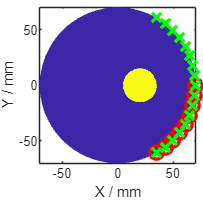

% -----------Desired sizes (cm)
% figW = 17.2/2;   % figure width
% figH = 17.2/2*0.618;    % figure height
% axW  = figW -4.5*0.282;    % axes width
% axH  = figH -4.5*0.282;    % axes height
% axLeft = 4*0.282;  % left margin (from figure left edge)
% axBottom = 4*0.282; % bottom margin

figW = 17.2/4;   % figure width
figH = 17.2/4;    % figure height
axW  = figW -3.5*0.282;    % axes width
axH  = figH -3.5*0.282;    % axes height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin

% -------- Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

set(fig1, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax1, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

mesh_for_plot = circle_mesh;
node_dist = vecnorm(mesh_for_plot.nodes,2,2);
tumor_distance = vecnorm(mesh_for_plot.nodes-[20 0 0],2,2);
% mesh_for_plot.mua((node_dist>=55)&(node_dist<=58)) = 0.0420;
mesh_for_plot.mua((tumor_distance<=15)) = 0.0620;



source_radius = base_radius-0.01; source_angle_rad = linspace(-pi/3,0,9)';
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_radius = base_radius-0.01; mea_angle_rad = linspace(-pi/3,pi/3,17)';
mea_pos = [mea_radius*cos(mea_angle_rad),mea_radius*sin(mea_angle_rad)];


trisurf(mesh_for_plot.elements,...
    mesh_for_plot.nodes(:,1),...
    mesh_for_plot.nodes(:,2),...
    mesh_for_plot.nodes(:,3),...
    mesh_for_plot.mua,'Parent',ax1 ...
    );
grid off
shading interp;
hold on

ps = plot(ax1,src_pos(:,1),src_pos(:,2),'ro','LineWidth',2,'MarkerSize',8,'Color',[1 0 0]);
pm = plot(ax1,mea_pos(:,1),mea_pos(:,2),'gx','LineWidth',2,'MarkerSize',8,'Color',[0 1 0]);

% hL = legend([ps,pm],{'Sources','Detectors'},'Location','northwest','FontName','Arial','FontSize',8);
% 1) Create your legend and let it choose the best location
drawnow;   % force it to render so Position is final


view(2);
axis equal 
% axis on;
colormap("parula")
% title('simulation setup')

%-- Beautify ----------------------------------------------------------------

xlabel('X / mm');
ylabel('Y / mm');

% xlim(ax1,[-72 72]);
% ylim(ax1,[-72 72]);

box(ax1,'on');
ax1.LineWidth = 1;
ax1.FontSize = 8;
ax1.FontName = 'Arial';



print(fig1, 'F1_1_140825.png', '-dpng', '-r1200');

addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\NIRFAST-9.1'));
addpath(genpath('D:\zhiguan_wang\OneDrive - University of Glasgow\project in UK 2024\tomography241015\NIRfast_code_241118\nirfast_fisher_numerical_311224'))
mua_value = 0.033; % 0.01
mus_value = 1;
tumour_pos = [35,0]; % 20 35
tumour_radius = 15;
base_radius = 70;
dense_dist = 0.5;
base_dist = 0.5;
circle_mesh = gen_nonuni_circle_mesh(tumour_pos,max(tumour_radius)+2*dense_dist,dense_dist,base_radius,base_dist,mua_value,mus_value,1.33);

d_mua = 0.02;

## plot figure for the paper Fig.1

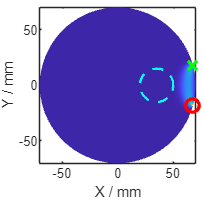

data_size = 17;
source_radius = base_radius-0.01; source_angle_rad = linspace(-pi/3,0,ceil(data_size/2))';
% source_radius = base_radius-0.01; source_angle_rad = pi/8;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
mea_radius = base_radius-0.01; mea_angle_rad = linspace(-pi/3,pi/3,data_size)';
% mea_radius = base_radius-0.01; mea_angle_rad = -pi/8;
mea_pos = [mea_radius*cos(mea_angle_rad),mea_radius*sin(mea_angle_rad)];

target_sd_pair = 113; % 20mm:83 35mm:113
 
[im,is] = ind2sub([size(mea_pos),size(src_pos,1)],target_sd_pair);

% % % % source-mea setup
mesh = circle_mesh; % renew the mesh
mesh.source.coord = src_pos(is,:);
mesh.meas.coord = mea_pos(im,:);

[ind_src,int_func_src] = mytsearchn(mesh,mesh.source.coord);
mesh.source.int_func = [ind_src int_func_src];
[ind_mea,int_func_mea] = mytsearchn(mesh,mesh.meas.coord);
mesh.meas.int_func = [ind_mea int_func_mea];

% -----------Desired sizes (cm)
% figW = 17.2/2;   % figure width
% figH = 17.2/2*0.618;    % figure height
% axW  = figW -4.5*0.282;    % axes width
% axH  = figH -4.5*0.282;    % axes height
% axLeft = 3.5*0.282;  % left margin (from figure left edge)
% axBottom = 3*0.282; % bottom margin

figW = 17.2/4;   % figure width
figH = 17.2/4;    % figure height
axW  = figW -3.5*0.282;    % axes width
axH  = figH -3.5*0.282;    % axes height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin


% -------- Create the figure at the given size
fig9 = figure;
ax9 = axes('Parent',fig9);

set(fig9, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax9, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig



mesh.source.distributed = 0;
mesh.source.fixed = 0;
mesh.source.num = 1;
mesh.source.fwhm = zeros(mesh.source.num);
mesh.link = [1 1 1];

mesh.meas.fixed = 0;
mesh.meas.num = 1;

mesh.source.coord = src_pos(is,:);
mesh.meas.coord = mea_pos(im,:);
[ind,int_func] = mytsearchn(mesh,mesh.meas.coord);
mesh.meas.int_func = [ind int_func];
jacobian_CW = jacobian_stnd(mesh,0);

optimal_tumour_size = 15 ;
distance2tumour = sqrt((mesh.nodes(:,1)-tumour_pos(1)).^2+(mesh.nodes(:,2)-tumour_pos(2)).^2);
mesh.mua(find(distance2tumour<optimal_tumour_size)) = mua_value + 0.02;

% % % %  plot tumour position

%-------------old plot mua----------------
% trisurf(mesh.elements,...
%     mesh.nodes(:,1),...
%     mesh.nodes(:,2),...
%     mesh.nodes(:,3),...
%     mesh.mua,'Parent',ax9 ...
%     );
%-------------old plot mua----------------

%-------------new plot Jacobian----------------
trisurf(mesh.elements,...
    mesh.nodes(:,1),...
    mesh.nodes(:,2),...
    mesh.nodes(:,3),...
    (abs(jacobian_CW.complete)),'Parent',ax9 ...
    ); hold on

xc = tumour_pos(1);    
yc = 0;    
r  = 15;  
t = linspace(0,2*pi,360);
x = xc + r*cos(t);
y = yc + r*sin(t);
pt = plot(ax9,x', y','--','LineWidth',1.5,'Color','c');
hold off
%-------------new plot Jacobian----------------


grid off
shading interp;
hold on
view(2);
axis equal                             
axis on;

box(ax9,'on');


xlabel('X / mm');
ylabel('Y / mm');


% axis equal tight;
axis on;
ax9.FontName = 'Arial';
ax9.FontSize = 8;
ax9.LineWidth = 1;
ps = plot(ax9,src_pos(is,1),src_pos(is,2),'ro','LineWidth',2,'MarkerSize',8,'Color',[1 0 0]);
pm = plot(ax9,mea_pos(im,1),mea_pos(im,2),'gx','LineWidth',2,'MarkerSize',8,'Color',[0 1 0]);

% hL = legend([ps,pm,pt],{'optimal source','optimal detector','defect'},'Location','northwest','FontName','Arial','FontSize',8);

print(fig9, 'F1-3_new.png', '-dpng', '-r1200');